# Integral length scale of turbulence: a short comparison

## Summary

The present file gives some of the methods commonly used to estimate the integral length scale (ILS). The ILS is used in wind engineering for wind loading on structures and in atmospheric science to identify typical scales of turbulence.

The data used hereinafter were simulated using [windSim function](https://se.mathworks.com/matlabcentral/fileexchange/50041-wind-field-simulation-text-based-input?s_tid=srchtitle), in particular the example1, which is described in detail [here](https://viewer.mathworks.com/?viewer=live_code&url=https%3A%2F%2Fse.mathworks.com%2Fmatlabcentral%2Fmlc-downloads%2Fdownloads%2Fb303e250-5b3e-4b60-9d6f-9cc95ca4a8c1%2Fdad14331-0d25-4060-ad1b-c92fdfddebf3%2Ffiles%2FExample1.mlx&embed=web). The wind speed data are simulated in 20 locations along a horizontal line.  The three velocity components are denoted $u$, $v$ and $w$. These are 20x36001 matrices. The time vector is $t$, which is a 1x36001 vector. The duration of the time series is 1h with a sampling frequency of 10 Hz. The location of the simulation points is given by the variable $nodes$.

Since the ILS is a 1-point integral turbulence characteristic, its estimation only requires one measurement location. With twenty locations, we can obtain 20 estimates of the integral length scales for homogeneous turbulence. There is one ILS per component. Since there are three velocity components, the ILSs are: $L^x_u$, $L^x_v$ and $L^x_w$. The notations and conventions used are summarized in [1] and are similar as in atmospheric science (axis $z$ is vertical positive and axis $x$ is parallel to the mean wind direction)

**References**

[1] Cheynet, E. (2016). Wind-induced vibrations of a suspension bridge: A case study in full-scale. PhD thesis. University of Stavanger, Norway

## Load the data

clearvars;close all;clc;

load('data.mat','u','v','w','t','nodes');
[Ny,N]=size(u);
meanU = nanmean(u,2);
dt = median(diff(t));

lux_target = 200; %  Target integral length scale used for the simulated data
lvx_target = 100; %  Target integral length scale used for the simulated data
lwx_target = 40; %  Target integral length scale used for the simulated data

## Integral length scales with the autocovariance function

Two methods are used with the autocovariance function: direct integration of the autocovariance function up to the first zero crossing (method = 1) or fit of an exponential decay (method = 2). The results shows a larger variability for the along-wind component  $u$ than the other two components ( $v$ and $w$) .

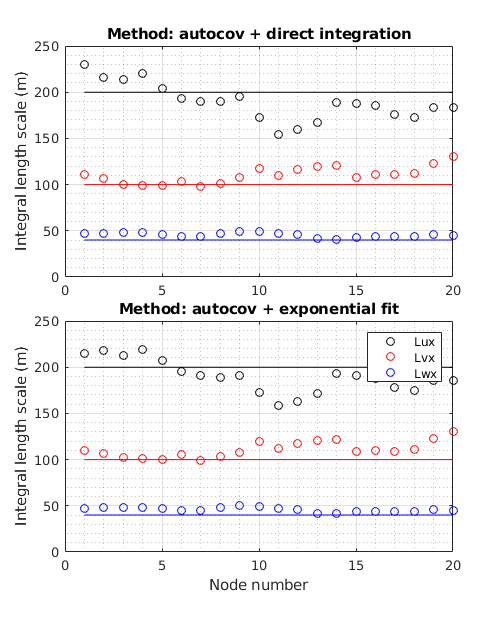


% preallocation
Lux_xcov1 = zeros(1,Ny); %  Integral length scale for u with method 1
Lvx_xcov1 = zeros(1,Ny); %  Integral length scale for v with method 1
Lwx_xcov1 = zeros(1,Ny); %  Integral length scale for w with method 1
Lux_xcov2 = zeros(1,Ny); %  Integral length scale for u with method 2
Lvx_xcov2 = zeros(1,Ny); %  Integral length scale for v with method 2
Lwx_xcov2 = zeros(1,Ny); %  Integral length scale for w with method 2

% compute the ILSs
for ii=1:Ny
    Lux_xcov1(ii) = Lx(u(ii,:),meanU(ii),dt,'method',1); % direct integration method
    Lvx_xcov1(ii) = Lx(v(ii,:),meanU(ii),dt,'method',1);
    Lwx_xcov1(ii) = Lx(w(ii,:),meanU(ii),dt,'method',1);
    
    Lux_xcov2(ii) = Lx(u(ii,:),meanU(ii),dt,'method',2); % Exponential fit method
    Lvx_xcov2(ii) = Lx(v(ii,:),meanU(ii),dt,'method',2);
    Lwx_xcov2(ii) = Lx(w(ii,:),meanU(ii),dt,'method',2);    
end

Ny = numel(nodes.Y);

clf;close all;
figure('position',[500,500,500,620])
tiledlayout(2,1,'tilespacing','none')
nexttile
plot(1:Ny,Lux_xcov1,'ko',1:Ny,Lvx_xcov1,'ro',1:Ny,Lwx_xcov1,'bo')
hold on
plot([1 Ny],[lux_target,lux_target],'k')
plot([1 Ny],[lvx_target,lvx_target],'r')
plot([1 Ny],[lwx_target,lwx_target],'b')
ylabel('Integral length scale (m)')
title('Method: autocov + direct integration')
grid on;grid minor

nexttile
plot(1:Ny,Lux_xcov2,'ko',1:Ny,Lvx_xcov2,'ro',1:Ny,Lwx_xcov2,'bo')
hold on
plot([1 Ny],[lux_target,lux_target],'k')
plot([1 Ny],[lvx_target,lvx_target],'r')
plot([1 Ny],[lwx_target,lwx_target],'b')
legend('Lux','Lvx','Lwx')
grid on;grid minor
ylim([0 250])
xlabel('Node number')
ylabel('Integral length scale (m)')
title('Method: autocov + exponential fit')

set(gcf,'color','w')



## Integral length scale with the von karman spectrum fit

This method relies on the fit of the von Karman spectrum to the estimated spectra, Note that the simulated wind speed data used the von karman spectrum too, so the spectrum fit will naturally shows a better agreement with the target values. 

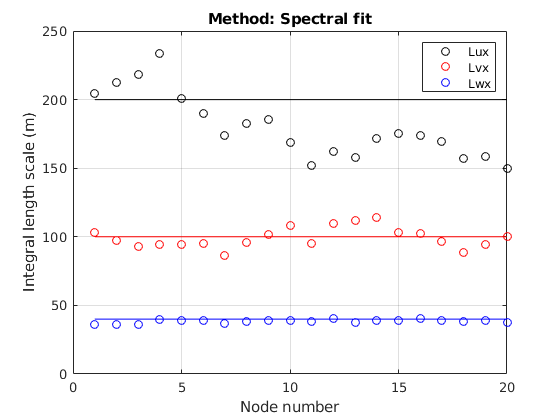


Lux_vK = zeros(1,Ny); %  Integral length scale for u
Lvx_vK = zeros(1,Ny); %  Integral length scale for v
Lwx_vK = zeros(1,Ny); %  Integral length scale for w

for ii=1:Ny
    [Lux_vK(ii),newSu,newF,Su,f]  = fitvK(u(ii,:),meanU(ii),dt,'u');
    [Lvx_vK(ii),newSv,newF,Sv,f] = fitvK(v(ii,:),meanU(ii),dt,'v');
    [Lwx_vK(ii),newSw,newF,Sw,f] = fitvK(w(ii,:),meanU(ii),dt,'w');
end

clf;close all;
plot(1:Ny,Lux_vK,'ko',1:Ny,Lvx_vK,'ro',1:Ny,Lwx_vK,'bo')
hold on
plot([1 Ny],[lux_target,lux_target],'k')
plot([1 Ny],[lvx_target,lvx_target],'r')
plot([1 Ny],[lwx_target,lwx_target],'b')
legend('Lux','Lvx','Lwx')
grid on
ylim([0 250])
xlabel('Node number')
ylabel('Integral length scale (m)')
title('Method: Spectral fit')

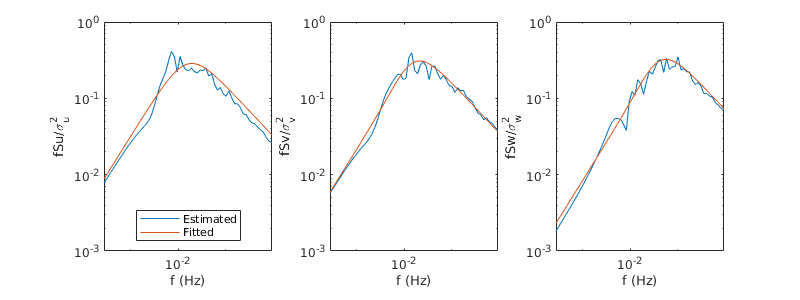

set(gcf,'color','w')
%% Fitted vs estimated spectra
clf;close all;
figure('position',[500,500,800,300])
tiledlayout(1,3,'tilespacing','none')
nexttile
loglog(f,f.*Su,newF,newF.*newSu)
xlabel('f (Hz)');
ylabel('fSu/\sigma^2_u');
axis tight
ylim([1e-3,1])
legend('Estimated','Fitted','location','south')

nexttile
loglog(f,f.*Sv,newF,newF.*newSv)
xlabel('f (Hz)');
ylabel('fSv/\sigma^2_v');
axis tight
ylim([1e-3,1])

nexttile
loglog(f,f.*Sw,newF,newF.*newSw)
xlabel('f (Hz)');
ylabel('fSw/\sigma^2_w');
axis tight
ylim([1e-3,1])


set(gcf,'color','w')

## Comparison of the two methods to estimate the integral length scale

As shown in these figures, the autocovariance method leads often to an overestimation of the ILSs. The random error associated with $u$ component is much larger than for the other two components. This is because $L^x_u$ is significantly affected by low-frequencies fluctuations and u contains more energy in the low-frequency range than $v$ and $w$. Using time series longer than 1 h will reduce the uncertainties, but only if the fluctuations are stationaries. Non-stationary data will lead to excessively large values of the integral length scales.

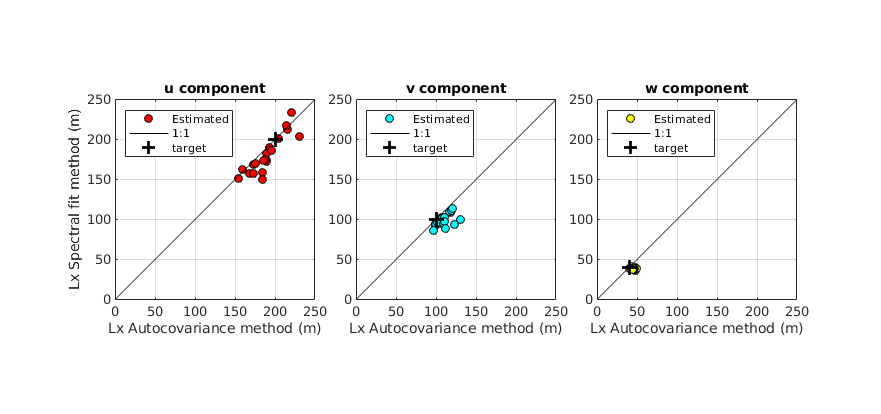

clf;close all;

figure('position',[565,565         881         414])
tiledlayout(1,3,'tilespacing','none')

nexttile
plot(Lux_xcov1,Lux_vK,'ko','markerfacecolor','r')
hold on
plot([0 250],[0 250],'k')
plot(lux_target,lux_target,'k+','markersize',10,'linewidth',2)
axis equal
grid on
ylim([0 250])
xlim([0 250])
xlabel('Lx Autocovariance method (m)')
ylabel('Lx Spectral fit method (m)')
title('u component')

legend('Estimated','1:1','target','location','northwest')

nexttile
plot(Lvx_xcov1,Lvx_vK,'ko','markerfacecolor','c')
hold on
plot([0 250],[0 250],'k')
axis equal
grid on
ylim([0 250])
xlim([0 250])
plot(lvx_target,lvx_target,'k+','markersize',10,'linewidth',2)
xlabel('Lx Autocovariance method (m)')
title('v component')

legend('Estimated','1:1','target','location','northwest')

nexttile
plot(Lwx_xcov1,Lwx_vK,'ko','markerfacecolor','y')
hold on
plot([0 250],[0 250],'k')
axis equal
grid on
ylim([0 250])
xlim([0 250])
plot(lwx_target,lwx_target,'k+','markersize',10,'linewidth',2)
xlabel('Lx Autocovariance method (m)')
title('w component')
set(gcf,'color','w')
legend('Estimated','1:1','target','location','northwest')

## Conclusions

 In a natural environment, it is unclear which of the two methods explored here (autocovariance of spectral fit) is better. The choice of the method depends on the application. For wind loading on structures, the use of the spectral fit is likely more appropriate. The autocovariance method can lead to an overestimation of the ILS due to its sensitivity to non-stationary fluctuations. If the ILSs are overestimated with the autocovariance function, and if the von Karman spectrum is used, the wind loading may be underestimated [1].